clc; clearvars; close all;
% Computation of weighting functions W3 for Hinf controller design
% Multiplicative model uncertainties
% Uncertainty in Ku, T, and Tw

set(groot, 'defaultAxesFontSize', 9)
set(groot, 'defaultTextFontSize', 10)
set(groot, 'defaultAxesTickLabelInterpreter','latex')
set(groot, 'defaultTextInterpreter','latex')

s = tf('s');

% Parameters
p = params();
cellfun(@(f) assignin('caller',f,p.(f)), fieldnames(p));

% Mode selection
mode = "island";   % "island" or "sync"
omega_p = omega_nom;

% Operating point

if mode == "island"

    fun = @(x) steady_equations(x, p, omega_p, 0);
    x0 = [1; 0.2];
    sol = fsolve(fun, x0);

elseif mode == "sync"

    P_el_target = 60e6;
    fun = @(x) steady_equations(x, p, omega_p, P_el_target/omega_nom);
    x0 = [5; 0.5];
    sol = fsolve(fun, x0);

else
    error("Unknown mode");
end


Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the step size tolerance squared and the vector of function values
is near zero as measured by the value of the function tolerance.

<stopping criteria details>



V_p = sol(1);
u_p = sol(2);

Q_p  = A * V_p;
hf_p = f*L/(2*D*g)*V_p^2;
Hb_p = HL - hf_p;

fprintf('Working point:\n');

Working point:


fprintf('V_p = %.3f m/s\n', V_p);

V_p = 0.189 m/s


fprintf('u_p = %.3f\n', u_p);

u_p = 0.065


fprintf('Q_p = %.3f m3/s\n', Q_p);

Q_p = 3.009 m3/s


fprintf('Hb_p = %.3f m\n', Hb_p);

Hb_p = 169.999 m


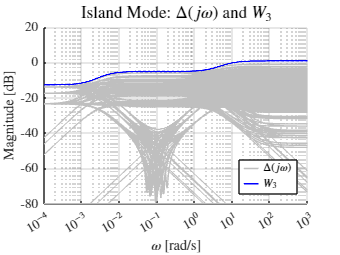


% Constants of the linear model

B  = (g*A)/a;
Kh = (k*u_p)/(2*sqrt(Hb_p-Ht));
Ku = k*sqrt(Hb_p-Ht);

CQ = (rho*g*eta_t)*(Hb_p-Ht)/omega_p;
CH = (rho*g*eta_t)*Q_p/omega_p;
Cw = (rho*g*eta_t)*Q_p*(Hb_p-Ht)/omega_p^2;

Dw = b + c*omega_p;
T  = I/(Cw+Dw);
tau = (Nx-1)*dt;

delay = exp(-2*tau*s);

num_h = (B*CQ - CH) + (B*CQ + CH)*delay;
den_h = (Kh + B) + (B - Kh)*delay;

% Nominal transfer function

Ku0 = Ku;
T0  = T;
Tw0 = Tw;

G_h0    = Ku0 * num_h / den_h;
G_mech0 = 1 / ((Cw+Dw)*(T0*s + 1));
G_f0    = 1 / (Tw0*s + 1);

if mode == "island"
    G0 = G_h0 * G_mech0 * G_f0;
elseif mode == "sync"
    G0 = G_h0 * G_f0;
end

% Uncertainty ranges

Ku_values = linspace(0.8*Ku0, 1.2*Ku0, 7);
T_values  = linspace(0.8*T0,  1.2*T0,  7);
Tw_values = linspace(0.8*Tw0, 1.2*Tw0, 7);


delta = {};
idx = 1;

if mode == "island"

    for i = 1:length(T_values)
    for j = 1:length(Tw_values)
    for k = 1:length(Ku_values)

        Tvar  = T_values(i);
        Twvar = Tw_values(j);
        Kuvar = Ku_values(k);

        G_h_var = Kuvar * num_h / den_h;
        G_mech_var = 1 / ((Cw+Dw)*(Tvar*s + 1));
        G_f_var = 1 / (Twvar*s + 1);

        G_var = G_h_var * G_mech_var * G_f_var;

        delta{idx} = (G_var / G0) - 1;
        idx = idx + 1;

    end
    end
    end

elseif mode == "sync"

    for j = 1:length(Tw_values)
    for k = 1:length(Ku_values)

        Twvar = Tw_values(j);
        Kuvar = Ku_values(k);

        G_h_var = Kuvar * num_h / den_h;
        G_f_var = 1 / (Twvar*s + 1);

        G_var = G_h_var * G_f_var;

        delta{idx} = (G_var / G0) - 1;
        idx = idx + 1;

    end
    end

end

% Plot

w = logspace(-4, 3, 1000);

figure; hold on;

h_delta = [];  % handle for legend

for i = 1:length(delta)
    resp = squeeze(freqresp(delta{i}, w));
    mag_lin = abs(resp);

    floor_lin = 10^(-80/20);
    mag_lin(mag_lin < floor_lin) = floor_lin;

    mag = 20*log10(mag_lin);

    if i == 1
        % The first curve is included in the legend
        h_delta = semilogx(w, mag, 'Color', [0.75 0.75 0.75], 'LineWidth', 1);
    else
        % Hide the remaining curves from the legend
        semilogx(w, mag, 'Color', [0.75 0.75 0.75], ...
                 'HandleVisibility', 'off');
    end
end

grid on
xlabel('$\omega$ [rad/s]')
ylabel('Magnitude [dB]')

if mode == "island"
    title('Island Mode: $\Delta(j\omega)$ and $W_3$', ...
          'Interpreter','latex', 'FontSize', 11)
else
    title('Synchronous Mode: $\Delta(j\omega)$ and $W_3$', ...
          'Interpreter','latex', 'FontSize', 11)
end

set(gca, 'XScale', 'log');
xlim([1e-4 1e3]);
xticks([1e-4 1e-3 1e-2 1e-1 1 1e1 1e2 1e3]);

hold on
if mode =="island"
    W3 = ss(0.23*tf(conv(1,conv([0.3 1],[600 1])),conv([0.15 1],[250 1])));
    W1 = ss(100*(1/((s+0.001)*(0.5*T*s+1))));
elseif mode == "sync"
    LF = db2mag(-13);
    HF = db2mag(-5.3);
    wc = 2;
    W3 = LF * tf([1/wc 1], [LF/(HF*wc) 1]);
    W1 = ss(0.678*((s/2.5)+0.2)/(s+0.2));
end

resp_W3 = squeeze(freqresp(W3, w));
mag_W3  = 20*log10(abs(resp_W3));
h_W3 = semilogx(w, mag_W3, 'b', 'LineWidth', 1);
lgd = legend([h_delta, h_W3], {'$\Delta(j\omega)$', '$W_3$'},'Interpreter','latex','Location', 'southeast');
lgd.ItemTokenSize = [10 6];
hold off
% Size for LaTeX
set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0 0 8 6]);

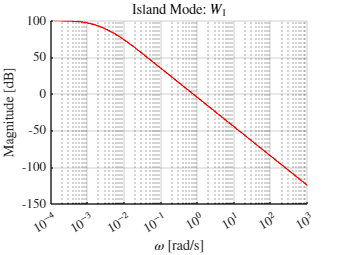


% Export
%exportgraphics(gcf, 'W3_delta_sync.pdf', 'ContentType', 'vector','Resolution',300);

figure
w1 = logspace(-4, 3, 1000); 

resp_W1 = squeeze(freqresp(W1, w1));
mag_W1  = 20*log10(abs(resp_W1));

semilogx(w1, mag_W1, 'r', 'LineWidth', 1);

grid on
xlabel('$\omega$ [rad/s]')
ylabel('Magnitude [dB]')
if mode == "island"
    title('Island Mode: $W_1$', 'Interpreter','latex', 'FontSize', 11)
else
    title('Synchronous Mode: $W_1$', 'Interpreter','latex', 'FontSize', 11)
end

set(gca, 'XScale', 'log');
xlim([1e-4 1e3]);   % extended range
xticks([1e-4 1e-3 1e-2 1e-1 1 1e1 1e2 1e3]);
box off

% Size for LaTeX
set(gcf, 'Units', 'centimeters');
set(gcf, 'Position', [0 0 8 6]);


% Export
%exportgraphics(gcf, 'W1_sync.pdf', 'ContentType', 'vector','Resolution',300);